%Punkty pracyh

clear all;
hpp  = [27.2 45.6 64 82.4 100.8];
Upp = zeros(length(hpp), 1);

t_span = 1:2000; Ts = 10; 
alfa1 = 13; alfa2 = 12;
z_signal = ones(floor(length(t_span)/Ts), 1) * 15;

for i = 1:length(hpp)

    Upp(i)  = calculate_Upp(hpp(i),15);
    
    % figure;
    % subplot(3,2,i)
    % h2_0_lin = hpp(i);
    % h1_0_lin = h2_0_lin * (alfa2 / alfa1)^2;
    % u_signal = ones(floor(length(t_span)/Ts), 1) * Upp(i);
    % [~, h] = linear_tank_model_v2(t_span, h1_0_lin, h2_0_lin, h2_0_lin, Ts, u_signal, z_signal);
    % stairs(h);
end







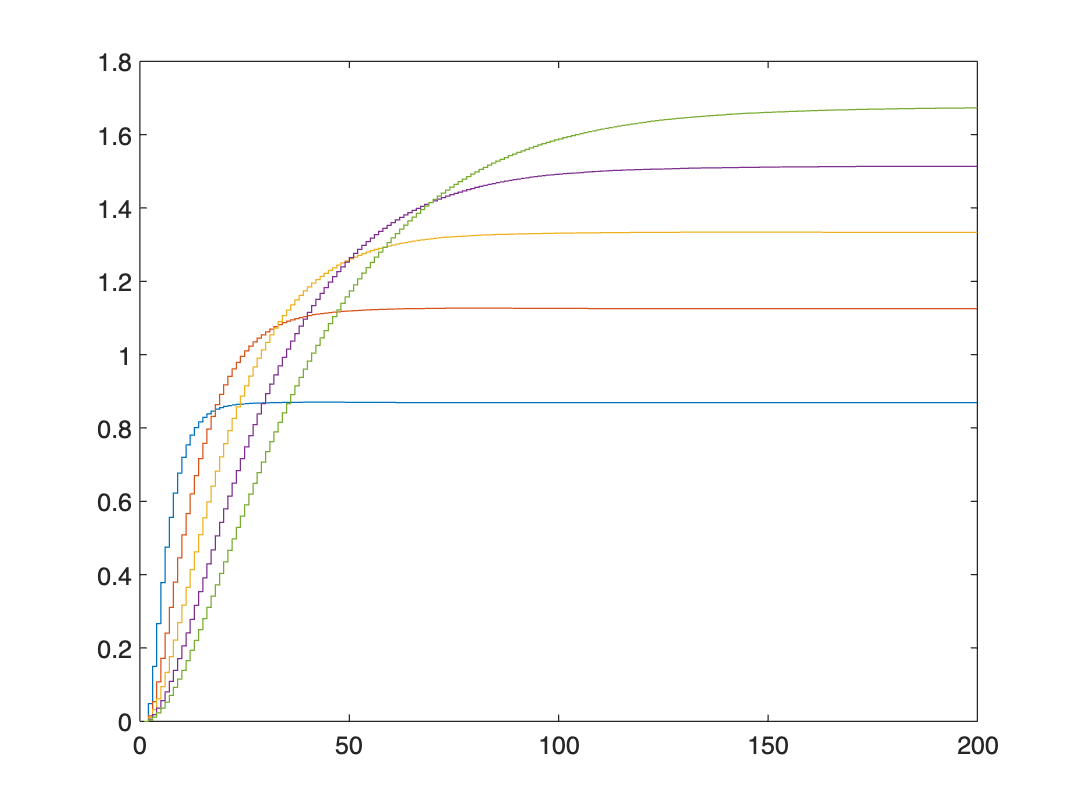

% s

S = [];
figure;
for i = 1:length(hpp)
    s = get_s_lin(2000, Ts, hpp(i), Upp(i));
    S = [S s];
    stairs(1:length(s), s);
    hold on
end
hold off

%fuzzy DMC 
D = 150; N = 70; Nu = 40; lambda = 1;
ke = [];
Ku = [];

for i = 1:size(S,2)
    [~, ~, ~, ke_new, Ku_new] = offline_DMC(S(:,i), D, N, Nu, lambda);
    ke(end+1) = ke_new;
    Ku(:,end+1) = Ku_new;
end




